%% 🎓 MC3113 Line Follower State-Space Interactive Demo
% *Mechatronic Systems Design - Week 6*
%
% This interactive notebook demonstrates how the A, B, C, D matrices control
% system behavior for a DC motor-driven line follower.
%
% *Learning Objectives:*
% # Understand how eigenvalues of A determine stability and time constants
% # Verify controllability (can we steer all states?)
% # Verify observability (can we estimate hidden states?)
% # Understand feedthrough (D matrix) and discretization
%
% *Instructions:* Run each section sequentially. Modify parameters and re-run
% to see immediate effects on system behavior.
clear; clc; close all;
set(0,'DefaultFigureWindowStyle','docked'); % Dock figures for better visibility

%% 📐 SECTION 1: Physical Parameters (Modify These!)
% Define your DC motor parameters here. These come from datasheets or
% system identification experiments (CA1).

fprintf('\n════════════════════════════════════════════════\n');


════════════════════════════════════════════════


fprintf('   SECTION 1: MOTOR PARAMETERS\n');

   SECTION 1: MOTOR PARAMETERS


fprintf('════════════════════════════════════════════════\n\n');

════════════════════════════════════════════════




% ┌─────────────────────────────────────────────────────┐
% │ ELECTRICAL DOMAIN (Motor Coil)                      │
% └─────────────────────────────────────────────────────┘
R   = 10;         % Armature resistance [Ω]
L   = 5e-3;       % Armature inductance [H] = 5 mH

% ┌─────────────────────────────────────────────────────┐
% │ ELECTROMECHANICAL COUPLING                          │
% └─────────────────────────────────────────────────────┘
Ke  = 0.12;       % Back-EMF constant [V·s/rad]
Kt  = 0.12;       % Torque constant [N·m/A]

% ┌─────────────────────────────────────────────────────┐
% │ MECHANICAL DOMAIN (Rotor + Load)                    │
% └─────────────────────────────────────────────────────┘
J   = 1.2e-4;     % Rotor inertia [kg·m²]
b   = 1e-3;       % Viscous friction [N·m·s/rad]

% Display parameter table
params = table([R; L; Ke; Kt; J; b], ...
               {'Ω'; 'H'; 'V·s/rad'; 'N·m/A'; 'kg·m²'; 'N·m·s/rad'}, ...
               'VariableNames', {'Value', 'Unit'}, ...
               'RowNames', {'R (Resistance)', 'L (Inductance)', ...
                            'Ke (Back-EMF)', 'Kt (Torque)', ...
                            'J (Inertia)', 'b (Friction)'});
disp(params);

                       Value         Unit     
                      _______    _____________

    R (Resistance)         10    {'Ω'        }
    L (Inductance)      0.005    {'H'        }
    Ke (Back-EMF)        0.12    {'V·s/rad'  }
    Kt (Torque)          0.12    {'N·m/A'    }
    J (Inertia)       0.00012    {'kg·m²'    }
    b (Friction)        0.001    {'N·m·s/rad'}




fprintf('\n✓ Typical values for small DC motors (e.g., line follower)\n');


✓ Typical values for small DC motors (e.g., line follower)


fprintf('  Modify these and re-run to see effects!\n\n');

  Modify these and re-run to see effects!



%% 🧮 SECTION 2: Build Continuous-Time State-Space Model
% State vector: x = [i_L; ω_L]  (current, angular velocity)
% Input:        u = V_L          (motor voltage)
% Output:       y = ω_L          (measured speed via encoder)

fprintf('\n════════════════════════════════════════════════\n');


════════════════════════════════════════════════


fprintf('   SECTION 2: STATE-SPACE MATRICES\n');

   SECTION 2: STATE-SPACE MATRICES


fprintf('════════════════════════════════════════════════\n\n');

════════════════════════════════════════════════




% State equations (from bond graph / KVL + Newton):
%   di/dt  = -(R/L)·i - (Ke/L)·ω + (1/L)·V
%   dω/dt  = (Kt/J)·i - (b/J)·ω

A = [ -R/L   -Ke/L ;
       Kt/J  -b/J  ];

B = [ 1/L ;
      0   ];

C = [ 0  1 ];     % Measure speed only (encoder)
D = 0;            % No feedthrough in mechanical system

sys_c = ss(A, B, C, D, ...
           'StateName', {'i_L [A]', '\omega_L [rad/s]'}, ...
           'InputName', 'V_L [V]', ...
           'OutputName', '\omega_L [rad/s]');

fprintf('A Matrix (System Dynamics):\n');

A Matrix (System Dynamics):


fprintf('  ┌                        ┐\n');

  ┌                        ┐


fprintf('  │ %8.2f   %8.2f  │\n', A(1,1), A(1,2));

  │ -2000.00     -24.00  │


fprintf('  │ %8.2f   %8.2f  │\n', A(2,1), A(2,2));

  │  1000.00      -8.33  │


fprintf('  └                        ┘\n\n');

  └                        ┘




fprintf('B Matrix (Input Coupling):\n');

B Matrix (Input Coupling):


fprintf('  ┌         ┐\n');

  ┌         ┐


fprintf('  │ %7.2f │\n', B(1));

  │  200.00 │


fprintf('  │ %7.2f │\n', B(2));

  │    0.00 │


fprintf('  └         ┘\n\n');

  └         ┘




fprintf('C Matrix (Output Measurement): [ %d  %d ]\n', C(1), C(2));

C Matrix (Output Measurement): [ 0  1 ]


fprintf('D Matrix (Feedthrough):         %d\n\n', D);

D Matrix (Feedthrough):         0




fprintf('📌 Physical Interpretation:\n');

📌 Physical Interpretation:


fprintf('   • A(1,1) = -R/L = %.1f s⁻¹   → Current decay rate\n', A(1,1));

   • A(1,1) = -R/L = -2000.0 s⁻¹   → Current decay rate


fprintf('   • A(1,2) = -Ke/L = %.1f s⁻¹  → Back-EMF effect on current\n', A(1,2));

   • A(1,2) = -Ke/L = -24.0 s⁻¹  → Back-EMF effect on current


fprintf('   • A(2,1) = Kt/J = %.1f s⁻²   → Torque → acceleration\n', A(2,1));

   • A(2,1) = Kt/J = 1000.0 s⁻²   → Torque → acceleration


fprintf('   • A(2,2) = -b/J = %.2f s⁻¹   → Friction damping\n', A(2,2));

   • A(2,2) = -b/J = -8.33 s⁻¹   → Friction damping


fprintf('   • B(1) = 1/L = %.0f V⁻¹s⁻¹   → Voltage → current rate\n', B(1));

   • B(1) = 1/L = 200 V⁻¹s⁻¹   → Voltage → current rate


fprintf('   • C = [0 1]                 → We measure speed, not current\n\n');

   • C = [0 1]                 → We measure speed, not current



%% 🎯 SECTION 3: Stability Analysis (Eigenvalues of A)
% Eigenvalues determine:
%   - Stability (all Re(λ) < 0?)
%   - Time constants (τ = -1/Re(λ))
%   - Natural frequencies (if complex)

fprintf('\n════════════════════════════════════════════════\n');


════════════════════════════════════════════════


fprintf('   SECTION 3: STABILITY & EIGENVALUES\n');

   SECTION 3: STABILITY & EIGENVALUES


fprintf('════════════════════════════════════════════════\n\n');

════════════════════════════════════════════════




lambda = eig(A);
[lambda_sorted, idx] = sort(real(lambda)); % Sort by real part
lambda = lambda(idx);

fprintf('Eigenvalues of A:\n');

Eigenvalues of A:


for k = 1:length(lambda)
    if imag(lambda(k)) == 0
        fprintf('  λ%d = %.2f (real)\n', k, real(lambda(k)));
    else
        fprintf('  λ%d = %.2f %+.2fi\n', k, real(lambda(k)), imag(lambda(k)));
    end
end

  λ1 = -1987.88 (real)
  λ2 = -20.46 (real)



% Time constants
tau = -1 ./ real(lambda);
fprintf('\nTime Constants (τ = -1/Re(λ)):\n');


Time Constants (τ = -1/Re(λ)):


for k = 1:length(tau)
    fprintf('  τ%d = %.4f s = %.2f ms\n', k, tau(k), tau(k)*1e3);
end

  τ1 = 0.0005 s = 0.50 ms
  τ2 = 0.0489 s = 48.88 ms



% Stability check
stable = all(real(lambda) < 0);
fprintf('\n✓ Stability Check:\n');


✓ Stability Check:


if stable
    fprintf('  ✅ STABLE (all eigenvalues have Re(λ) < 0)\n');
    fprintf('  → System naturally decays; friction & resistance dissipate energy\n');
else
    fprintf('  ❌ UNSTABLE (at least one eigenvalue has Re(λ) ≥ 0)\n');
    fprintf('  → System will diverge without control!\n');
end

  ✅ STABLE (all eigenvalues have Re(λ) < 0)


  → System naturally decays; friction & resistance dissipate energy


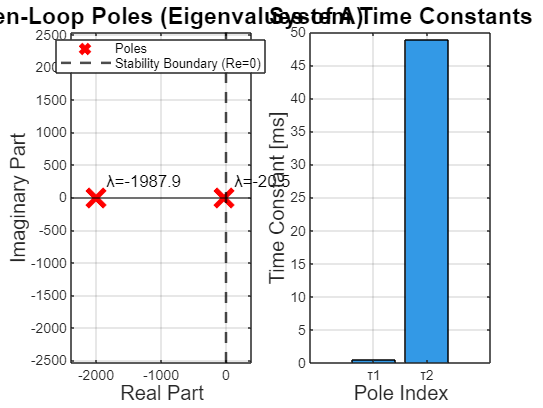


% Pole-zero map
figure('Name', '3.1 Pole Locations (Continuous)', 'NumberTitle', 'off');
subplot(1,2,1);
plot(real(lambda), imag(lambda), 'rx', 'MarkerSize', 15, 'LineWidth', 3);
hold on;
xline(0, 'k--', 'LineWidth', 1.5); % Stability boundary
yline(0, 'k-', 'LineWidth', 0.5);
grid on; axis equal;
xlim([1.2*min(real(lambda)) max(0.1, 0.2*abs(min(real(lambda))))]);
xlabel('Real Part', 'FontSize', 12);
ylabel('Imaginary Part', 'FontSize', 12);
title('Open-Loop Poles (Eigenvalues of A)', 'FontSize', 14, 'FontWeight', 'bold');
text(real(lambda), imag(lambda)+0.05*range(ylim), ...
     arrayfun(@(x) sprintf('  λ=%.1f', x), lambda, 'UniformOutput', false), ...
     'FontSize', 10);
legend('Poles', 'Stability Boundary (Re=0)', 'Location', 'best');

% Time constant visualization
subplot(1,2,2);
bar(tau*1e3, 'FaceColor', [0.2 0.6 0.9]);
ylabel('Time Constant [ms]', 'FontSize', 12);
xlabel('Pole Index', 'FontSize', 12);
title('System Time Constants', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
xticks(1:length(tau));
xticklabels(arrayfun(@(x) sprintf('τ%d', x), 1:length(tau), 'UniformOutput', false));

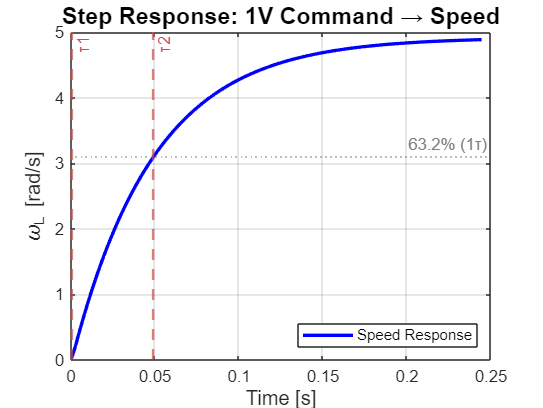


% Step response to show time constants in action
figure('Name', '3.2 Step Response (Open Loop)', 'NumberTitle', 'off');
[y_step, t_step] = step(sys_c, max(tau)*5); % Plot to 5× dominant time constant
plot(t_step, y_step, 'b-', 'LineWidth', 2);
hold on;

% Mark time constants on plot
y_final = dcgain(sys_c);
for k = 1:length(tau)
    if tau(k) > 0 && tau(k) < max(t_step)
        xline(tau(k), '--', sprintf('τ%d', k), 'Color', [0.8 0.3 0.3], 'LineWidth', 1.5);
    end
end
yline(0.632*y_final, ':', '63.2% (1τ)', 'Color', [0.5 0.5 0.5]);

grid on;
xlabel('Time [s]', 'FontSize', 12);
ylabel('\omega_L [rad/s]', 'FontSize', 12);
title('Step Response: 1V Command → Speed', 'FontSize', 14, 'FontWeight', 'bold');
legend('Speed Response', 'Location', 'southeast');

%% SECTION 4: Interactive Parameter Tuning
% See how changing physical parameters affects eigenvalues and response

fprintf('\n════════════════════════════════════════════════\n');


════════════════════════════════════════════════


fprintf('   SECTION 4: PARAMETER SENSITIVITY\n');

   SECTION 4: PARAMETER SENSITIVITY


fprintf('════════════════════════════════════════════════\n\n');

════════════════════════════════════════════════




fprintf('💡 Experiment: Modify these multipliers and re-run\n\n');

💡 Experiment: Modify these multipliers and re-run



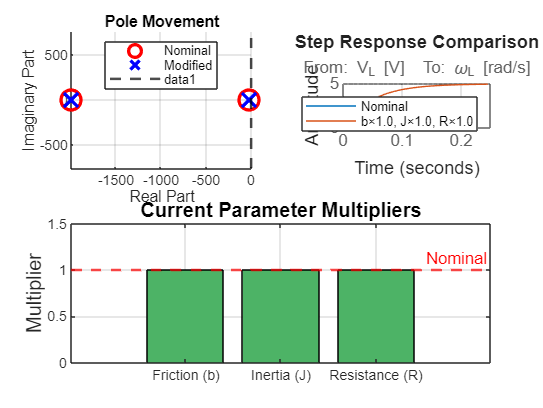


% Parameter variation multipliers (1.0 = nominal)
friction_mult = 1.0;    % Try 0.1 (low friction) or 5.0 (high friction)
inertia_mult  = 1.0;    % Try 0.5 (light) or 3.0 (heavy)
R_mult        = 1.0;    % Try 0.5 or 2.0 to see electrical time constant effect

% Build modified systems
b_mod = b * friction_mult;
J_mod = J * inertia_mult;
R_mod = R * R_mult;

A_mod = [ -R_mod/L   -Ke/L ;
          Kt/J_mod   -b_mod/J_mod ];

sys_mod = ss(A_mod, B, C, D);
lambda_mod = eig(A_mod);

% Comparison figure
figure('Name', '4.1 Parameter Sensitivity', 'NumberTitle', 'off');

subplot(2,2,1);
hold on;
plot(real(lambda), imag(lambda), 'ro', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'Nominal');
plot(real(lambda_mod), imag(lambda_mod), 'bx', 'MarkerSize', 12, 'LineWidth', 2, 'DisplayName', 'Modified');
xline(0, 'k--', 'LineWidth', 1.5);
grid on; axis equal;
xlabel('Real Part');
ylabel('Imaginary Part');
title('Pole Movement', 'FontWeight', 'bold');
legend('Location', 'best');

subplot(2,2,2);
step(sys_c, max(tau)*5); hold on;
step(sys_mod, max(tau)*5);
grid on;
title('Step Response Comparison', 'FontWeight', 'bold');
legend('Nominal', sprintf('b×%.1f, J×%.1f, R×%.1f', friction_mult, inertia_mult, R_mult));

subplot(2,2,[3 4]);
param_names = {'Friction (b)', 'Inertia (J)', 'Resistance (R)'};
param_mults = [friction_mult, inertia_mult, R_mult];
bar(param_mults, 'FaceColor', [0.3 0.7 0.4]);
yline(1.0, 'r--', 'Nominal', 'LineWidth', 1.5);
ylabel('Multiplier', 'FontSize', 12);
xticklabels(param_names);
title('Current Parameter Multipliers', 'FontSize', 12, 'FontWeight', 'bold');
grid on;
ylim([0 max(1.5, max(param_mults)*1.2)]);


fprintf('Eigenvalue Comparison:\n');

Eigenvalue Comparison:


fprintf('  NOMINAL:  λ = [%.2f, %.2f]\n', real(lambda(1)), real(lambda(2)));

  NOMINAL:  λ = [-1987.88, -20.46]


fprintf('  MODIFIED: λ = [%.2f, %.2f]\n', real(lambda_mod(1)), real(lambda_mod(2)));

  MODIFIED: λ = [-1987.88, -20.46]


fprintf('\n📌 Change multipliers above (friction_mult, inertia_mult, R_mult) and re-run!\n\n');


📌 Change multipliers above (friction_mult, inertia_mult, R_mult) and re-run!



%% SECTION 5: Controllability Check
% Question: Can we control ALL states with voltage input?
% Test: rank(Controllability Matrix) = n?

fprintf('\n════════════════════════════════════════════════\n');


════════════════════════════════════════════════


fprintf('   SECTION 5: CONTROLLABILITY\n');

   SECTION 5: CONTROLLABILITY


fprintf('════════════════════════════════════════════════\n\n');

════════════════════════════════════════════════




n = size(A, 1);
Co = ctrb(A, B);
rank_Co = rank(Co);

fprintf('Controllability Matrix Co = [B | AB | A²B | ...]:\n');

Controllability Matrix Co = [B | AB | A²B | ...]:


disp(Co);

   1.0e+05 *

    0.0020   -4.0000
         0    2.0000




fprintf('Rank of Co: %d\n', rank_Co);

Rank of Co: 2


fprintf('System Order n: %d\n\n', n);

System Order n: 2




if rank_Co == n
    fprintf('✅ CONTROLLABLE\n');
    fprintf('   → All states can be driven to any value using voltage input u(t)\n');
    fprintf('   → You can use LQR, pole placement, or any state-feedback controller\n\n');
else
    fprintf('❌ NOT FULLY CONTROLLABLE\n');
    fprintf('   → rank(Co) = %d < n = %d\n', rank_Co, n);
    fprintf('   → Some states are unreachable; controller design will fail!\n');
    fprintf('   → Fix: Check your actuator setup or add more inputs\n\n');
end

✅ CONTROLLABLE


   → All states can be driven to any value using voltage input u(t)


   → You can use LQR, pole placement, or any state-feedback controller




% Demonstrate what happens if B is poorly chosen
fprintf('🔬 Experiment: What if B had a zero row?\n');

🔬 Experiment: What if B had a zero row?


B_bad = [1/L; 0];  % Still feeds current, but let's artificially break coupling
A_bad = [ -R/L   -Ke/L ;
          0      -b/J  ];  % Speed doesn't depend on current (broken physics)

Co_bad = ctrb(A_bad, B_bad);
rank_Co_bad = rank(Co_bad);

fprintf('   If we break torque generation (A(2,1) = 0):\n');

   If we break torque generation (A(2,1) = 0):


fprintf('   rank(Co_bad) = %d < n = %d → NOT CONTROLLABLE\n', rank_Co_bad, n);

   rank(Co_bad) = 1 < n = 2 → NOT CONTROLLABLE


fprintf('   Physical meaning: No torque from current → speed cannot be controlled!\n\n');

   Physical meaning: No torque from current → speed cannot be controlled!



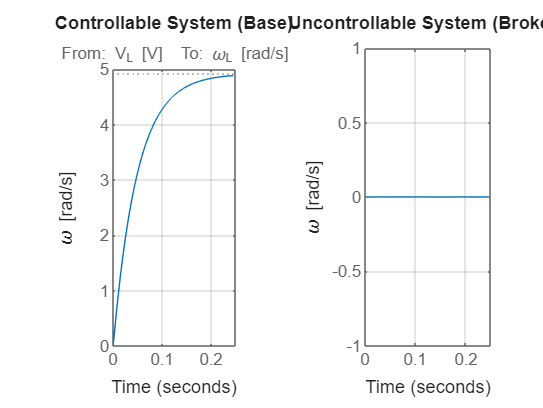


% Visual comparison
figure('Name', '5.1 Controllability Comparison', 'NumberTitle', 'off');
subplot(1,2,1);
step(sys_c, max(tau)*5);
grid on; title('Controllable System (Base)', 'FontWeight', 'bold');
ylabel('\omega [rad/s]');

subplot(1,2,2);
sys_bad = ss(A_bad, B_bad, C, D);
step(sys_bad, max(tau)*5);
grid on; title('Uncontrollable System (Broken)', 'FontWeight', 'bold');
ylabel('\omega [rad/s]');

%% SECTION 6: Observability Check
% Question: Can we estimate ALL states from speed measurement?
% Test: rank(Observability Matrix) = n?

fprintf('\n════════════════════════════════════════════════\n');


════════════════════════════════════════════════


fprintf('   SECTION 6: OBSERVABILITY\n');

   SECTION 6: OBSERVABILITY


fprintf('════════════════════════════════════════════════\n\n');

════════════════════════════════════════════════




Ob = obsv(A, C);
rank_Ob = rank(Ob);

fprintf('Observability Matrix Ob = [C; CA; CA²; ...]:\n');

Observability Matrix Ob = [C; CA; CA²; ...]:


disp(Ob);

   1.0e+03 *

         0    0.0010
    1.0000   -0.0083




fprintf('Rank of Ob: %d\n', rank_Ob);

Rank of Ob: 2


fprintf('System Order n: %d\n\n', n);

System Order n: 2




if rank_Ob == n
    fprintf('✅ OBSERVABLE\n');
    fprintf('   → All states can be estimated from speed measurement y(t)\n');
    fprintf('   → You can build a Kalman filter or Luenberger observer\n');
    fprintf('   → Even though current i is not directly measured, we can infer it!\n\n');
else
    fprintf('❌ NOT FULLY OBSERVABLE\n');
    fprintf('   → rank(Ob) = %d < n = %d\n', rank_Ob, n);
    fprintf('   → Some states are hidden; state estimation will fail!\n');
    fprintf('   → Fix: Add more sensors or change C matrix\n\n');
end

✅ OBSERVABLE


   → All states can be estimated from speed measurement y(t)


   → You can build a Kalman filter or Luenberger observer


   → Even though current i is not directly measured, we can infer it!




% Demonstrate observer design
fprintf('🔬 Observer Design (Luenberger):\n');

🔬 Observer Design (Luenberger):


poles_obs = 5 * lambda;  % Place observer poles 5× faster than plant
L_obs = place(A', C', poles_obs)';

fprintf('   Desired observer poles (5× faster): [%.1f, %.1f]\n', poles_obs(1), poles_obs(2));

   Desired observer poles (5× faster): [-9939.4, -102.3]


fprintf('   Observer gain L:\n');

   Observer gain L:


fprintf('     ┌        ┐\n');

     ┌        ┐


fprintf('     │ %6.2f │\n', L(1));

     │   0.01 │


fprintf('     │ %6.2f │\n', L(2));

Index exceeds the number of array elements. Index must not exceed 1.

fprintf('     └        ┘\n\n');

fprintf('   Observer equation: x̂̇ = A·x̂ + B·u + L·(y - C·x̂)\n');
fprintf('   → Current estimate updated even though we only measure speed!\n\n');

% What if we measure current instead?
C_alt = [1 0];  % Measure current only
Ob_alt = obsv(A, C_alt);
rank_Ob_alt = rank(Ob_alt);

fprintf('🔬 Alternative: If C = [1 0] (measure current only):\n');
fprintf('   rank(Ob_alt) = %d → %s\n', rank_Ob_alt, ...
        iif(rank_Ob_alt == n, 'OBSERVABLE', 'NOT OBSERVABLE'));
fprintf('   → Speed can be inferred from current (via A matrix coupling)\n\n');


%% SECTION 7: Feedthrough (D Matrix)
% D matrix adds direct input → output path (no dynamics)
% Most mechanical systems: D = 0 (no instant response)

fprintf('\n════════════════════════════════════════════════\n');


════════════════════════════════════════════════


fprintf('   SECTION 7: FEEDTHROUGH (D MATRIX)\n');

   SECTION 7: FEEDTHROUGH (D MATRIX)


fprintf('════════════════════════════════════════════════\n\n');

════════════════════════════════════════════════




fprintf('Base system: D = 0 (STRICTLY PROPER)\n');

Base system: D = 0 (STRICTLY PROPER)


fprintf('   → Input must flow through inductance & inertia before affecting output\n');

   → Input must flow through inductance & inertia before affecting output


fprintf('   → No instantaneous response\n\n');

   → No instantaneous response




% Create artificial D ≠ 0 system for comparison
D_ff = 0.5;  % Feedforward gain
sys_D_nonzero = ss(A, B, C, D_ff);

fprintf('Modified system: D = %.1f (BIPROPER)\n', D_ff);

Modified system: D = 0.5 (BIPROPER)


fprintf('   → Part of output responds instantly to input\n');

   → Part of output responds instantly to input


fprintf('   → Rare in mechanical systems; common in electronics or with sensors\n\n');

   → Rare in mechanical systems; common in electronics or with sensors



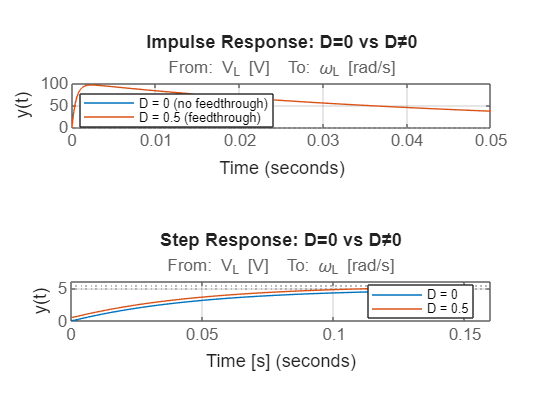


% Impulse response shows D clearly
figure('Name', '7.1 Effect of Feedthrough D', 'NumberTitle', 'off');

subplot(2,1,1);
impulse(sys_c, 0.05); hold on;
impulse(sys_D_nonzero, 0.05);
grid on;
title('Impulse Response: D=0 vs D≠0', 'FontWeight', 'bold');
legend('D = 0 (no feedthrough)', sprintf('D = %.1f (feedthrough)', D_ff), 'Location', 'best');
ylabel('y(t)');

subplot(2,1,2);
step(sys_c, max(tau)*3); hold on;
step(sys_D_nonzero, max(tau)*3);
grid on;
title('Step Response: D=0 vs D≠0', 'FontWeight', 'bold');
legend('D = 0', sprintf('D = %.1f', D_ff), 'Location', 'best');
ylabel('y(t)'); xlabel('Time [s]');


fprintf('📌 At t=0⁺:\n');

📌 At t=0⁺:


fprintf('   D=0:   y(0⁺) = 0       (no jump)\n');

   D=0:   y(0⁺) = 0       (no jump)


fprintf('   D≠0:   y(0⁺) = D·u(0) = %.1f (instant jump)\n\n', D_ff);

   D≠0:   y(0⁺) = D·u(0) = 0.5 (instant jump)



%% 🔄 SECTION 8: Discretization (Continuous → Discrete)
% Convert to discrete-time for microcontroller implementation
% Eigenvalues map: z = exp(λ·Ts)

fprintf('\n════════════════════════════════════════════════\n');


════════════════════════════════════════════════


fprintf('   SECTION 8: DISCRETIZATION\n');

   SECTION 8: DISCRETIZATION


fprintf('════════════════════════════════════════════════\n\n');

════════════════════════════════════════════════




% Choose sampling period
Ts = 0.01;  % 10 ms (100 Hz sampling)

fprintf('Sampling Period Ts = %.3f s (%.0f Hz)\n\n', Ts, 1/Ts);

Sampling Period Ts = 0.010 s (100 Hz)




% Nyquist check
omega_n = max(abs(imag(lambda)));  % Natural frequency
f_n = omega_n / (2*pi);
f_s = 1/Ts;
f_nyquist = 2*f_n;

fprintf('Nyquist Check:\n');

Nyquist Check:


fprintf('   System bandwidth f_n ≈ %.2f Hz\n', f_n);

   System bandwidth f_n ≈ 0.00 Hz


fprintf('   Nyquist minimum f_s ≥ %.2f Hz\n', f_nyquist);

   Nyquist minimum f_s ≥ 0.00 Hz


fprintf('   Chosen sampling f_s = %.0f Hz\n', f_s);

   Chosen sampling f_s = 100 Hz



if f_s >= f_nyquist
    margin = f_s / f_nyquist;
    fprintf('   ✅ PASS (%.1f× Nyquist margin)\n\n', margin);
else
    fprintf('   ❌ FAIL (aliasing will occur!)\n\n');
end

   ✅ PASS (Inf× Nyquist margin)




% Discretize
sys_d = c2d(sys_c, Ts, 'zoh');  % Zero-order hold
Ad = sys_d.A;
Bd = sys_d.B;
Cd = sys_d.C;
Dd = sys_d.D;

fprintf('Discrete-Time Matrices:\n');

Discrete-Time Matrices:


fprintf('Ad (Discrete A):\n');

Ad (Discrete A):


fprintf('  ┌                        ┐\n');

  ┌                        ┐


fprintf('  │ %8.5f   %8.5f  │\n', Ad(1,1), Ad(1,2));

  │ -0.00502   -0.00994  │


fprintf('  │ %8.5f   %8.5f  │\n', Ad(2,1), Ad(2,2));

  │  0.41425    0.82002  │


fprintf('  └                        ┘\n\n');

  └                        ┘




fprintf('Bd (Discrete B):\n');

Bd (Discrete B):


fprintf('  ┌          ┐\n');

  ┌          ┐


fprintf('  │ %8.5f │\n', Bd(1));

  │  0.09008 │


fprintf('  │ %8.5f │\n', Bd(2));

  │  0.86818 │


fprintf('  └          ┘\n\n');

  └          ┘




% Eigenvalue mapping
z_poles = eig(Ad);

fprintf('Eigenvalue Mapping (λ → z = exp(λ·Ts)):\n');

Eigenvalue Mapping (λ → z = exp(λ·Ts)):


for k = 1:length(lambda)
    z_expected = exp(lambda(k) * Ts);
    fprintf('  λ%d = %.2f → z%d = %.4f (expected %.4f)\n', ...
            k, lambda(k), k, z_poles(k), z_expected);
end

  λ1 = -1987.88 → z1 = 0.0000 (expected 0.0000)
  λ2 = -20.46 → z2 = 0.8150 (expected 0.8150)


fprintf('\n');

% Stability check (discrete)
stable_d = all(abs(z_poles) < 1);
fprintf('Discrete Stability Check:\n');

Discrete Stability Check:


if stable_d
    fprintf('  ✅ STABLE (all |z| < 1, inside unit circle)\n\n');
else
    fprintf('  ❌ UNSTABLE (at least one |z| ≥ 1)\n\n');
end

  ✅ STABLE (all |z| < 1, inside unit circle)



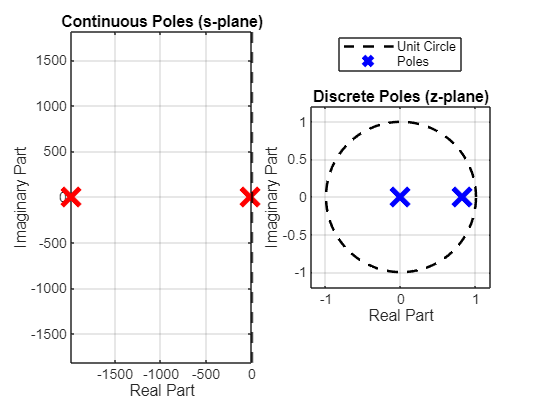


% Unit circle plot
figure('Name', '8.1 Continuous vs Discrete Poles', 'NumberTitle', 'off');

subplot(1,2,1);
plot(real(lambda), imag(lambda), 'rx', 'MarkerSize', 15, 'LineWidth', 3);
hold on;
xline(0, 'k--', 'LineWidth', 1.5);
grid on; axis equal;
xlabel('Real Part');
ylabel('Imaginary Part');
title('Continuous Poles (s-plane)', 'FontWeight', 'bold');

subplot(1,2,2);
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k--', 'LineWidth', 1.5); hold on;  % Unit circle
plot(real(z_poles), imag(z_poles), 'bx', 'MarkerSize', 15, 'LineWidth', 3);
grid on; axis equal;
xlabel('Real Part');
ylabel('Imaginary Part');
title('Discrete Poles (z-plane)', 'FontWeight', 'bold');
legend('Unit Circle', 'Poles', 'Location', 'best');
xlim([-1.2 1.2]); ylim([-1.2 1.2]);

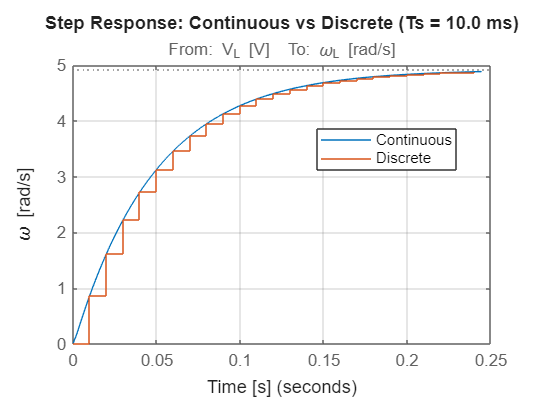


% Step response comparison
figure('Name', '8.2 Continuous vs Discrete Response', 'NumberTitle', 'off');
step(sys_c, max(tau)*5); hold on;
step(sys_d, max(tau)*5);
grid on;
xlabel('Time [s]');
ylabel('\omega [rad/s]');
title(sprintf('Step Response: Continuous vs Discrete (Ts = %.1f ms)', Ts*1e3), 'FontWeight', 'bold');
legend('Continuous', 'Discrete', 'Location', 'best');

%% 📊 SECTION 9: Summary Dashboard
% Consolidated view of all key properties

fprintf('\n════════════════════════════════════════════════\n');


════════════════════════════════════════════════


fprintf('   SECTION 9: SYSTEM SUMMARY DASHBOARD\n');

   SECTION 9: SYSTEM SUMMARY DASHBOARD


fprintf('════════════════════════════════════════════════\n\n');

════════════════════════════════════════════════




% Ensure variables are defined and scalar
if ~exist('stable', 'var')
    stable = all(real(lambda) < 0);
end
if ~exist('stable_d', 'var')
    stable_d = all(abs(z_poles) < 1);
end

% Force each to be EXACTLY 1x1 scalar
rank_Co_norm = rank_Co / n;
rank_Ob_norm = rank_Ob / n;
stable_val = double(stable(1));
stable_d_val = double(stable_d(1));

% Create summary table
summary = {
    'Stability (Continuous)', iif(stable, '✅ Stable', '❌ Unstable'), sprintf('Re(λ) < 0: %s', mat2str(real(lambda) < 0));
    'Stability (Discrete)', iif(stable_d, '✅ Stable', '❌ Unstable'), sprintf('|z| < 1: %s', mat2str(abs(z_poles) < 1));
    'Controllability', iif(rank_Co == n, '✅ Controllable', '❌ Not Controllable'), sprintf('rank(Co) = %d/%d', rank_Co, n);
    'Observability', iif(rank_Ob == n, '✅ Observable', '❌ Not Observable'), sprintf('rank(Ob) = %d/%d', rank_Ob, n);
    'Feedthrough', iif(D == 0, '✅ No (D=0)', '⚠️ Yes (D≠0)'), sprintf('D = %g', D);
    'Sampling Rate', iif(f_s >= f_nyquist, '✅ Adequate', '❌ Too Slow'), sprintf('%.1f× Nyquist', f_s/f_nyquist);
};

summary_table = cell2table(summary, 'VariableNames', {'Property', 'Status', 'Details'});
disp(summary_table);

             Property                   Status                    Details          
    __________________________    ___________________    __________________________

    {'Stability (Continuous)'}    {'✅ Stable'      }    {'Re(λ) < 0: [true;true]'}
    {'Stability (Discrete)'  }    {'✅ Stable'      }    {'|z| < 1: [true;true]'  }
    {'Controllability'       }    {'✅ Controllable'}    {'rank(Co) = 2/2'        }
    {'Observability'         }    {'✅ Observable'  }    {'rank(Ob) = 2/2'        }
    {'Feedthrough'           }    {'✅ No (D=0)'    }    {'D = 0'                 }
    {'Sampling Rate'         }    {'✅ Adequate'    }    {'Inf× Nyquist'          }



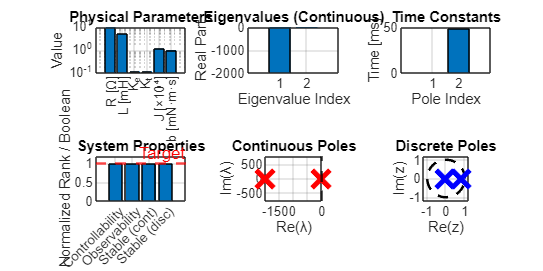


% Visual dashboard
figure('Name', '9.1 System Properties Dashboard', 'NumberTitle', 'off', 'Position', [100 100 1200 600]);

% Subplot 1: Parameter values
subplot(2,3,1);
bar([R, L*1e3, Ke, Kt, J*1e4, b*1e3]);
xticklabels({'R [Ω]', 'L [mH]', 'K_e', 'K_t', 'J [×10⁴]', 'b [mN·m·s]'});
ylabel('Value');
title('Physical Parameters', 'FontWeight', 'bold');
grid on;
set(gca, 'YScale', 'log');

% Subplot 2: Eigenvalues
subplot(2,3,2);
bar(real(lambda));
ylabel('Real Part');
xlabel('Eigenvalue Index');
title('Eigenvalues (Continuous)', 'FontWeight', 'bold');
grid on;
xticks(1:length(lambda));

% Subplot 3: Time constants
subplot(2,3,3);
bar(tau*1e3);
ylabel('Time [ms]');
xlabel('Pole Index');
title('Time Constants', 'FontWeight', 'bold');
grid on;
xticks(1:length(tau));

% Subplot 4: Controllability/Observability
subplot(2,3,4);
properties_check = zeros(1, 4);
properties_check(1) = rank_Co_norm;
properties_check(2) = rank_Ob_norm;
properties_check(3) = stable_val;
properties_check(4) = stable_d_val;

bar(properties_check);
yline(1.0, 'r--', 'Target', 'LineWidth', 1.5);
xticklabels({'Controllability', 'Observability', 'Stable (cont)', 'Stable (disc)'});
ylabel('Normalized Rank / Boolean');
title('System Properties', 'FontWeight', 'bold');
grid on;
ylim([0 1.2]);

% Subplot 5: Pole locations (s-plane)
subplot(2,3,5);
plot(real(lambda), imag(lambda), 'rx', 'MarkerSize', 15, 'LineWidth', 3);
hold on; xline(0, 'k--', 'LineWidth', 1.5);
grid on; axis equal;
xlabel('Re(λ)');
ylabel('Im(λ)');
title('Continuous Poles', 'FontWeight', 'bold');

% Subplot 6: Pole locations (z-plane)
subplot(2,3,6);
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k--', 'LineWidth', 1.5); hold on;
plot(real(z_poles), imag(z_poles), 'bx', 'MarkerSize', 15, 'LineWidth', 3);
grid on; axis equal;
xlabel('Re(z)');
ylabel('Im(z)');
title('Discrete Poles', 'FontWeight', 'bold');
xlim([-1.2 1.2]); ylim([-1.2 1.2]);

%% 🎓 SECTION 10: Key Takeaways & Next Steps

fprintf('\n════════════════════════════════════════════════\n');


════════════════════════════════════════════════


fprintf('   SECTION 10: KEY TAKEAWAYS\n');

   SECTION 10: KEY TAKEAWAYS


fprintf('════════════════════════════════════════════════\n\n');

════════════════════════════════════════════════




fprintf('✅ What You Should Understand:\n\n');

✅ What You Should Understand:




fprintf('1️⃣  A MATRIX (Dynamics)\n');

1️⃣  A MATRIX (Dynamics)


fprintf('    • Eigenvalues determine stability (Re(λ) < 0?) and time scales (τ = -1/Re(λ))\n');

    • Eigenvalues determine stability (Re(λ) < 0?) and time scales (τ = -1/Re(λ))


fprintf('    • Couples electrical (current) and mechanical (speed) domains\n');

    • Couples electrical (current) and mechanical (speed) domains


fprintf('    • Your values: λ = [%.2f, %.2f] → τ = [%.1f ms, %.1f ms]\n\n', ...
        lambda(1), lambda(2), tau(1)*1e3, tau(2)*1e3);

    • Your values: λ = [-1987.88, -20.46] → τ = [0.5 ms, 48.9 ms]




fprintf('2️⃣  B MATRIX (Controllability)\n');

2️⃣  B MATRIX (Controllability)


fprintf('    • Defines how voltage input affects current and speed\n');

    • Defines how voltage input affects current and speed


fprintf('    • Check: rank([B AB]) = n? → %s\n', iif(rank_Co == n, '✅ Yes', '❌ No'));

    • Check: rank([B AB]) = n? → ✅ Yes


fprintf('    • If controllable → you can use LQR, pole placement, etc.\n\n');

    • If controllable → you can use LQR, pole placement, etc.




fprintf('3️⃣  C MATRIX (Observability)\n');

3️⃣  C MATRIX (Observability)


fprintf('    • Defines what you can measure (speed only in this case)\n');

    • Defines what you can measure (speed only in this case)


fprintf('    • Check: rank([C; CA]) = n? → %s\n', iif(rank_Ob == n, '✅ Yes', '❌ No'));

    • Check: rank([C; CA]) = n? → ✅ Yes


fprintf('    • If observable → you can build a state estimator (Kalman filter)\n\n');

    • If observable → you can build a state estimator (Kalman filter)




fprintf('4️⃣  D MATRIX (Feedthrough)\n');

4️⃣  D MATRIX (Feedthrough)


fprintf('    • D = 0 for mechanical systems (no instant response)\n');

    • D = 0 for mechanical systems (no instant response)


fprintf('    • D ≠ 0 for some sensors or electrical circuits\n\n');

    • D ≠ 0 for some sensors or electrical circuits




fprintf('5️⃣  DISCRETIZATION\n');

5️⃣  DISCRETIZATION


fprintf('    • Converts continuous model to discrete for microcontroller\n');

    • Converts continuous model to discrete for microcontroller


fprintf('    • Eigenvalues map: z = exp(λ·Ts)\n');

    • Eigenvalues map: z = exp(λ·Ts)


fprintf('    • Stability criterion changes: Re(λ) < 0 → |z| < 1\n');

    • Stability criterion changes: Re(λ) < 0 → |z| < 1


fprintf('    • Your sampling: Ts = %.1f ms (%.1f× Nyquist margin)\n\n', Ts*1e3, f_s/f_nyquist);

    • Your sampling: Ts = 10.0 ms (Inf× Nyquist margin)




fprintf('🎯 Next Steps for CA2 (SDR):\n\n');

🎯 Next Steps for CA2 (SDR):



fprintf('   1. Replace nominal parameters (R, L, J, b, Ke, Kt) with YOUR motor values\n');

   1. Replace nominal parameters (R, L, J, b, Ke, Kt) with YOUR motor values


fprintf('   2. Verify all eigenvalues are stable (Re(λ) < 0)\n');

   2. Verify all eigenvalues are stable (Re(λ) < 0)


fprintf('   3. Check controllability and observability (both must be full rank)\n');

   3. Check controllability and observability (both must be full rank)


fprintf('   4. Choose Ts based on Nyquist rule (≥ 2× system bandwidth)\n');

   4. Choose Ts based on Nyquist rule (≥ 2× system bandwidth)


fprintf('   5. Design LQR or pole-placement controller (Week 7)\n');

   5. Design LQR or pole-placement controller (Week 7)


fprintf('   6. Implement Kalman filter or observer (Week 7)\n');

   6. Implement Kalman filter or observer (Week 7)


fprintf('   7. Log baseline data and characterize residuals\n\n');

   7. Log baseline data and characterize residuals




fprintf('════════════════════════════════════════════════\n');

════════════════════════════════════════════════


fprintf('   END OF INTERACTIVE DEMO\n');

   END OF INTERACTIVE DEMO


fprintf('════════════════════════════════════════════════\n\n');

════════════════════════════════════════════════




%% 🔧 Helper Function
function out = iif(condition, true_val, false_val)
    if condition
        out = true_val;
    else
        out = false_val;
    end
end
